# Flight Path Optimization with Code Generation

This script demonstrates the use of Optimization Toolbox to solve a simple pathfinding problem. In this version of the script, we use MATLAB® Coder™ to generate a MEX function or standalone C code for computing the optimal path.

We are given an airplane with a fixed airspeed and a vector field of wind in which to navigate. The objective is to find the path which minimizes the time taken to travel from the starting point to the finish point.

We will compare the solutions and speed of the versions with and without code generation. The code for optimizing the path must be in an external function in order to generate code, as must any functions that it calls. We created an external function named `optimizePath`.

## Set parameters

Use "pchip" as the interpolation method instead of allowing a choice. This reduces the changes needed for code generation. 

clear
AirSpeed = 500;
sizeX = 50;
sizeY = 25;
numWayPoints = 5;
randomSeed = 50;
rng(randomSeed);
integrationFineness = 101;

## Generate a random wind field

pathAxes = axes;
W_x = makeWindFun(sizeX,sizeY);
W_y = makeWindFun(sizeX,sizeY);
[Xgrid,Ygrid] = meshgrid(0:sizeX,0:sizeY);
hq = quiver(pathAxes,Xgrid,Ygrid,W_x,W_y,"k");
hold(pathAxes,"on");
xlabel(pathAxes,"Units = 100 [km]");
% axis equal tight
pathAxes.XLim = [0 sizeX];
pathAxes.YLim = [0 sizeY];
pathAxes.DataAspectRatio = [1 1 1];
plot(pathAxes,[0 sizeX],[sizeY sizeY]/2,"k.","MarkerSize",16)

Add some color to make it more visible by generating an image from the favorability of the wind to use as the background.

L = (sqrt((Xgrid-sizeX).^2 + (Ygrid-sizeY/2).^2));
Favorability = ((sizeX-Xgrid).*W_x +  (sizeY/2-Ygrid).*W_y)./L;
Favorability(~isfinite(Favorability)) = 0;

hold on;
h_im = imagesc(pathAxes,Favorability);
set(h_im,"Xdata",[0 sizeX],"Ydata",[0 sizeY]);
uistack(h_im,"bottom");

Change the colormap.

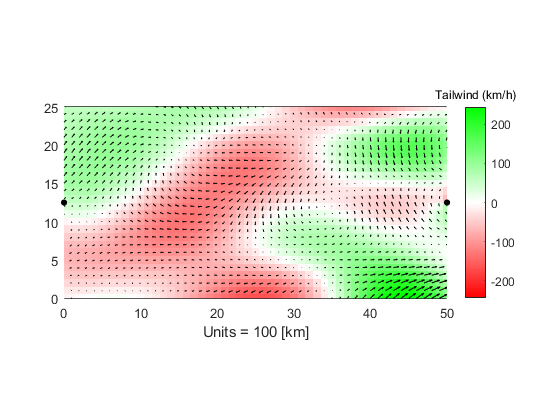

colormap(pathAxes,interp1([0,1,2],[1 0 0; 1 1 1; 0 1 0],0:0.01:2));
caxis(pathAxes,max(abs(Favorability(:)))*[-1 1]);

h_colorbar = colorbar(pathAxes);
title(h_colorbar,"Tailwind (km/h)")

## Find an optimal path using `fmincon`

Find the optimal waypoints. Define the objective function to minimize the time taken on the path interpolated from the waypoints. Record the time taken for the optimization to compare with the MEX version generated below.

objFcn = @()optimizePath(W_y,W_x,numWayPoints,integrationFineness,AirSpeed,sizeX,sizeY);
runTime = timeit(objFcn,1);
optimalWayPoints = optimizePath(W_y,W_x,numWayPoints,integrationFineness,AirSpeed,sizeX,sizeY);

### Plot the optimal solution

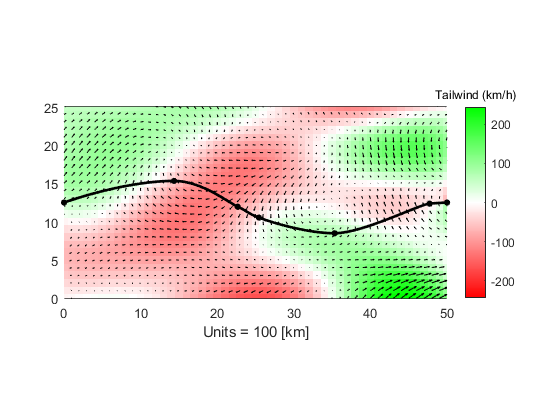

xWayPoints = optimalWayPoints(:,1);
yWayPoints = optimalWayPoints(:,2);
h_wp = plot(pathAxes,xWayPoints,yWayPoints,"color","k","linestyle","none","marker",".","markersize",16);

PathPoints = waypointsToPath([xWayPoints,yWayPoints],sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,PathPoints(:,1),PathPoints(:,2),"k","linewidth",2);

## Find an optimal path using a MEX function 

 Run compile_optimizePath_mex.m to build the MEX function optimizePath_mex with MATLAB Coder.

compile_optimizePath_mex

Code generation successful: View report


Run and time the generated MEX function

objFcn_mex = @()optimizePath_mex(W_y,W_x,numWayPoints,integrationFineness,AirSpeed,sizeX,sizeY);
runTime_mex = timeit(objFcn_mex,1);
optimalWayPoints_mex = optimizePath_mex(W_y,W_x,numWayPoints,integrationFineness,AirSpeed,sizeX,sizeY);

### Plot the optimal solution

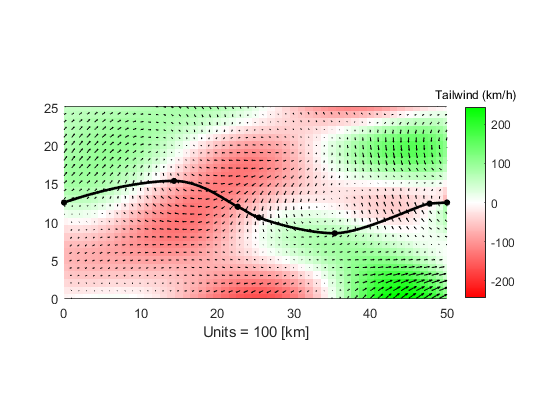

delete([h_wp h_path]);

xWayPoints = optimalWayPoints_mex(:,1);
yWayPoints = optimalWayPoints_mex(:,2);
h_wp = plot(pathAxes,xWayPoints,yWayPoints,"color","k","linestyle","none","Marker",".","MarkerSize",16);

PathPoints_mex = waypointsToPath([xWayPoints,yWayPoints],sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,PathPoints_mex(:,1),PathPoints_mex(:,2),"k","LineWidth",2);

## Compare run times and paths

LineTime = getTimeFromPath(PathPoints,W_x,W_y,AirSpeed);
fprintf("Optimal Travel Time: %d hours, %.2f minutes computed in %.4f seconds\n",...
    floor(LineTime),rem(LineTime,1)*60,runTime);

Optimal Travel Time: 10 hours, 17.83 minutes computed in 0.4812 seconds


LineTime = getTimeFromPath(PathPoints_mex,W_x,W_y,AirSpeed);
fprintf("Optimal Travel Time with Code Gen: %d hours, %.f minutes computed in %.4f seconds\n",...
    floor(LineTime),rem(LineTime,1)*60,runTime_mex);

Optimal Travel Time with Code Gen: 10 hours, 18 minutes computed in 0.0592 seconds


fprintf('Total difference between paths: %10.3e km\n',vecnorm(PathPoints(:) - PathPoints_mex(:), 2));

Total difference between paths:  5.114e-03 km


## Generate standalone C code

 Run compile_optimizePath_lib.m to use MATLAB Coder to generate standalone C code to deploy optimizePath

compile_optimizePath_lib

Code generation successful: View report


The generated code is produced in codegen/lib/optimizePath. To learn more about the generated code, click the **view report** link above.

Once you have the generated code see the MATLAB Coder documentation to learn about next steps:

- [How to use and deploy the generated code](https://www.mathworks.com/help/coder/deployment.html)

- [How to test the behavior of the generated code](https://www.mathworks.com/help/coder/ug/test-generated-cc-code.html)

- [Verifying the generated code with SIL and PIL](https://www.mathworks.com/help/ecoder/ug/code-verification-through-software-in-the-loop-and-processor-in-the-loop-execution.html) (Embedded Coder® required)

## Helper Functions

### makeWindFun

function iWind = makeWindFun(SZX,SZY)
% This is just a helper function to make a random scalar function. This is
% called twice to generate a random wind field.

windFineness = 0.1;
if ~exist("SZX","var")
    SZX = 50;
    SZY = 50;
end

N = 50; % Various parameters used in generating a random "smooth" matrix
NL = 40;
NP = 500;
rx = randn(NL,N);
rx = interpft(rx,NP);
ry = randn(NL,N);
ry = interpft(ry,NP);
I = (rx*ry');

[xgi,ygi] = meshgrid(linspace(1,2 + 498*windFineness,SZX+1),linspace(1,2 + 498*windFineness,SZY+1));
iWind = 10*interp2(1:500,1:500,I,xgi,ygi);
end

Copyright 2012-2019 The MathWorks, Inc. 